# Model $\frac{1}{4}$ zawieszenia

#### Mateusz Wójcik, 30.10.2024

## 1. Cele ćwiczenia

Celem tego ćwiczenia jest opracowanie bardziej zaawansowanego modelu matematycznego zawieszenia samochodu niż ten utworzony na poprzednich laboratoriach. Model będzie odnosił się tylko do jednego koła czyli $\frac{1}{4}$ zawieszenia, a następnie zostaną wykonanie symulacje tego modelu. Przeanalizowane zostaną odpowiedzi skokowe oraz odpowiedź systemu na serię wymuszeń, aby zasymulować uproszczone warunki drogowe. Po wykonaniu odpowiednich obliczeń model zostanie również odwzorowany w środowisku SIMULINK.

clear, clc, clf;

## Model w Matlabie

Model oparto na schemacie przedstawionym poniżej:

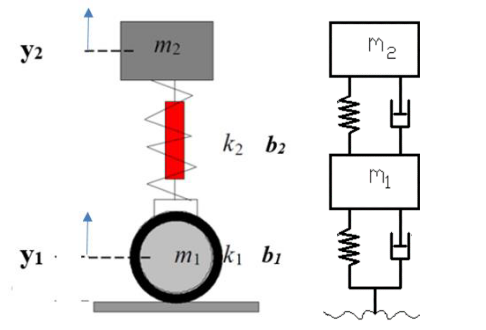

Punkt równowagi reprezentuje wstępne napięcia sprężyn pod wpływem sił ciężkości. **Dynamikę modelu opisują odchyłkowe zmienne y1(t) i y2(t) . **Sterowanie **u **przedstawia zmiany podłoża, na które musi reagować zawieszenie, aby móc zapewnić komfort jazdy. Jak widać na powyższym schemacie takie zawieszenie można uprościć do modelu zawierającego dwa tłumiki, dwie sprężyny i dwie masy, gdzie przyjęto następujące oznaczenia

#### Definicja zmiennych:

m1 = 50;     %kg - masa koła z wahaczem (części nieresorowanej podwozia),
m2 = 370;    %kg – masa ćwiartki nadwozia (części resorowanej), 
k1 = 220000; %N/m – współczynniki sprężystości opony,
k2 = 35000;  %N/m – współczynniki sprężystości sprężyny,
b1 = 500;    %Ns/m – współczynnik tłumienia opony,
b2 = 1000;   %Ns/m – współczynnik tłumienia amortyzatora olejowego

A $y_1$ i $y_2$ to:

$y_1$ – pionowe przesunięcie środka masy opony (względna odchyłka od stanu równowagi),

$y_2$ – pionowe przesunięcie środka masy nadwozia (względna odchyłka od stanu równowagi).

Na podstawie przyjętych oznaczeń otrzymano następująco dynamikę modelu liniowego:


$$m_1 \ddot{y}_1 + b_1 (\dot{y}_1 - \dot{u}) + b_2 (\dot{y}_1 - \dot{y}_2) + k_1 (y_1 - u) + k_2 (y_1 - y_2) = 0,$$



$$m_2 \ddot{y}_2 + b_2 (\dot{y}_2 - \dot{y}_1) + k_2 (y_2 - y_1) = 0$$


W celu pozbycia się pochodnej sygnału sterującgo w równaniach opisujących dynamikę układu, przyjęto następujące cztery zmienne stanu x(t):


$$x_1 = y_1,$$



$$x_2 = y_2,$$



$$x_3 = \dot{y}_1 - \left( \frac{b_1}{m_1} \right) u,$$



$$x_4 = \dot{y}_2$$


Teraz można przejśc na zmienne stanu w równaniu opisującym dynamikę układu liniowego i stworzyć macierze umożliwiające utworzenie obiektu w przestrzeni stanów.

#### Tworzenie macierzy reprezentujących przestrzeń stanów:

A =[[0 0 1 0];
    [0 0 0 1];
    [-(k1+k2)/m1 k2/m1 -(b1+b2)/m1 b2/m1];
    [k2/m2 -k2/m2 b2/m2 -b2/m2]];

B = [b1/m2; 0; k1/m1-(b1+b2)*b1/m1^2; b1*b2/(m1*m2)];
C = eye(4);
D = zeros([4, 1]);

#### Utworzenie obiektu w przestrzeni stanów

Poznano tutaj nową funkcjalność Matlaba, przydatną przy tworzeniu przestrzeni stanów. Jesteśmy w stanie przy tworzeniu obiektu zdefiniować tytułu zmiennych wejściowych, zmiennych stanu oraz zmiennych wyjściowych. Zaleta tego rozwiązania jest widoczna w dalszej części sprawozdania, gdzie bez zbędnych linijek kodu, Matlab odrazu tworzy nam podpisane wykresy.

sys = ss(A,B,C,D,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'});

Wykreślenie odpowiedzi skokowych dla czasu 2,5 sekundy.

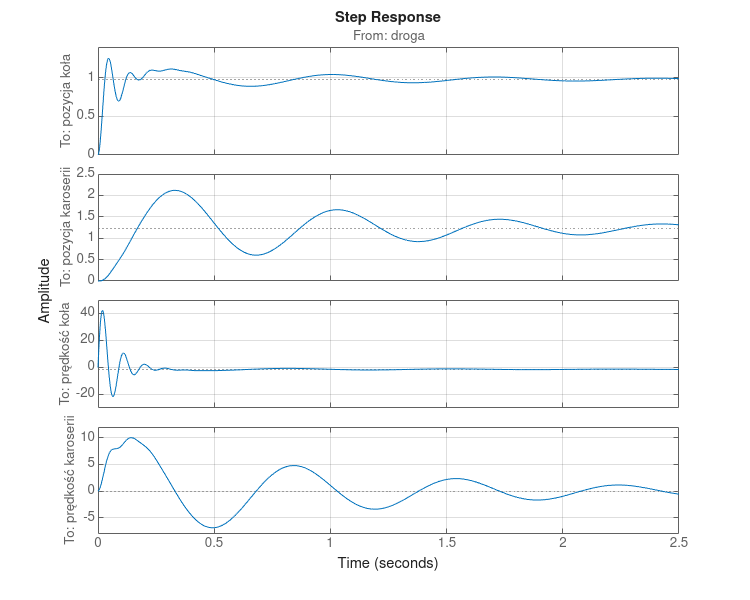

clf
figure
step(sys,0:0.001:2.5)
grid on
set(gcf, 'Position', [100, 100, 1000, 800]);

Wykres przedstawiający odpowiedź na wymuszenie skokowe jest zgodne z oczekiwaniami i po pewnym czasie pozycja karoserii ustabilizuje się w pozycji odpowiadającej skokowi. Widać, że zawieszenie znacznie tłumi nierówność podłoża - zmiany położenia karoserii zachodzą znacznie wolniej niż te, które są odczuwane przez koło. Trzeba natomiast uważać na zbyt mały czas próbkowania, który jak widać na poniższym wykresie potrafi całkowicie zmienić przebieg sygnału:

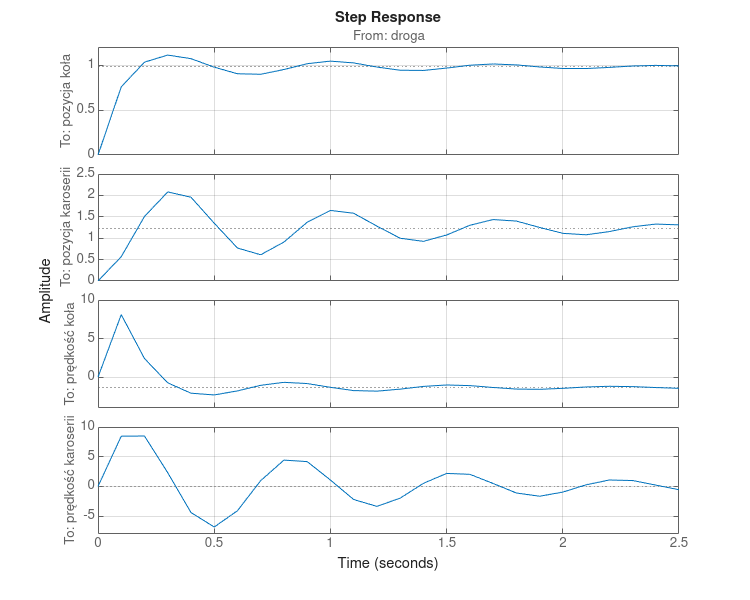

step(sys,0:0.1:2.5)
grid on

W celu sprawdzenia odpowiedzi na serię wymuszeń zasymulowano przy użyciu funkcji **lsim, **odpowiedź na falę prostokątną - sygnał u1 i na $sin^2(x)$ + wygenerowany szum - sygnał u2.

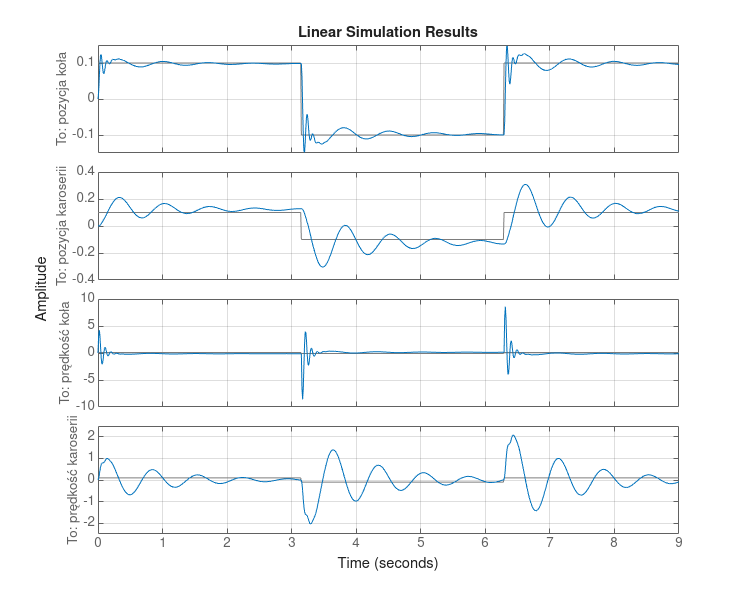

t = 0:0.01:9;
u1 = 0.1 * square(t); 
u2 = 0.3* (sin(t)).^2 + 0.05*rand([1,length(t)]);
lsim(sys,u1,t)
grid on

Na podstawie tych wyników widać, że układ zachowuje swoje własności również dla ujemnych skoków (zjeżdzania z krawężnika) - odpowiednio tłumiąc karoserie samochodu.

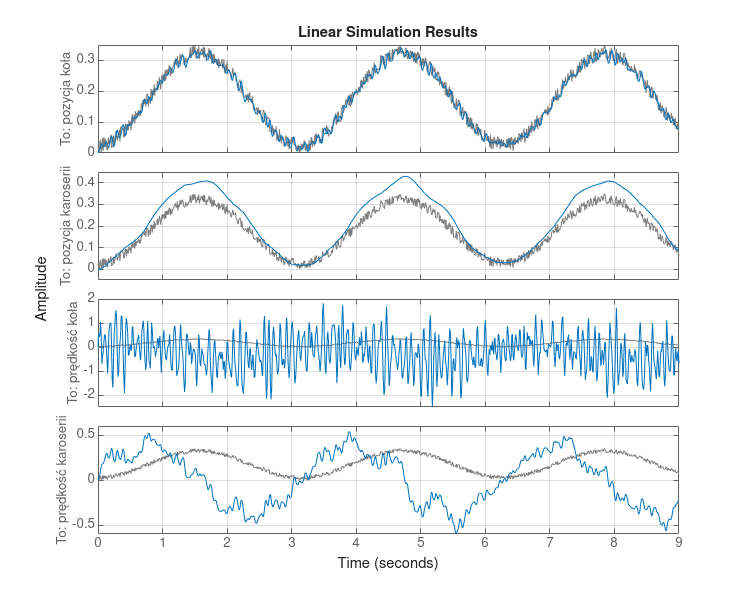

lsim(sys,u2,t)
grid on

Można zauważyć, że dla sygnału bardziej przypominającego nierówną drogę, zawieszenie również spełnia swoje zadanie. Małe zmiany drogi, które mogłyby powodować dyskomfort u pasażera są skutecznie tłumione i nie przenoszą się już na karoserie.

#### Przeprowadzenie modyfikacji w kodzie w celu uzyskania na wyjściu tylko pozycji koła i pozycji karoserii:

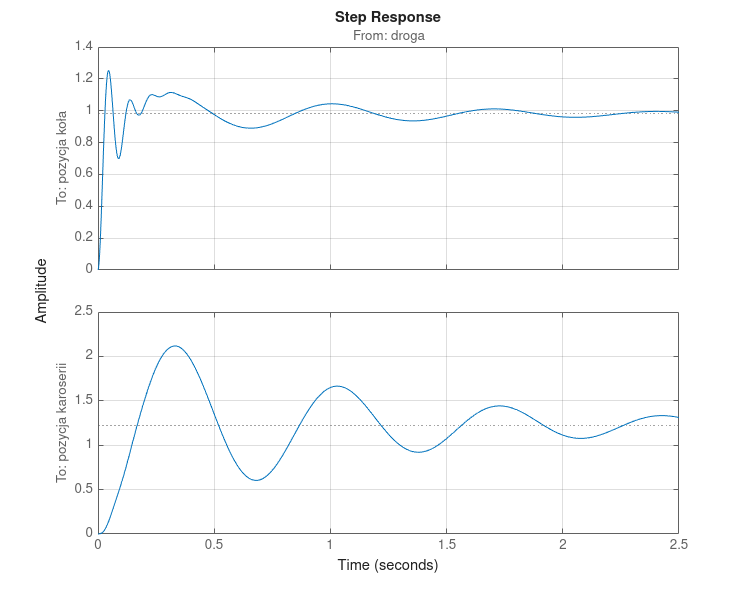

C_1 = eye(2,4);
D_1 = zeros([2,1]);
sys_1 = ss(A,B,C_1,D_1,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName', {'pozycja koła', 'pozycja karoserii'});
step(sys_1,0:0.001:2.5);
grid on

## Obliczanie transmitancji operatorowej

Kolejnym etapem ćwiczenia jest wyznaczenie transmitancji układu. W tym celu skporzystano z funkcji zamieniającej obiekt w przestrzeni stanów na wektory liczników i mianowników transmitancji. Układ posiada cztery wyjścia, dlatego uzyskano cztery różne transmitancje opisujące kolejno pozycje i prędkości koła/karoserii.

[licz,mian] = ss2tf(A,B,C,D);


#### Wyznaczone transmitancje:

G1 = tf(licz(1,:),mian,'InputName','droga','OutputName','pozycja koła')


G1 =
 
  From input "droga" to output "pozycja koła":
     1.351 s^3 + 4144 s^2 + 1.179e04 s + 4.08e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G2 = tf(licz(2,:),mian,'InputName','droga','OutputName','pozycja karoserii')


G2 =
 
  From input "droga" to output "pozycja karoserii":
          27.03 s^2 + 1.202e04 s + 5.109e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G3 = tf(licz(3,:),mian,'InputName','droga','OutputName','prędkość koła')


G3 =
 
  From input "droga" to output "prędkość koła":
     4100 s^3 + 4730 s^2 + 3.907e05 s - 5.625e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G4 = tf(licz(4,:),mian,'InputName','droga','OutputName','prędkość karoserii')


G4 =
 
  From input "droga" to output "prędkość karoserii":
  27.03 s^3 + 1.202e04 s^2 + 5.109e05 s + 5.45e-09
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


#### Następnie na podstawie transmitancji wyznaczono odpowiedzi skokowe

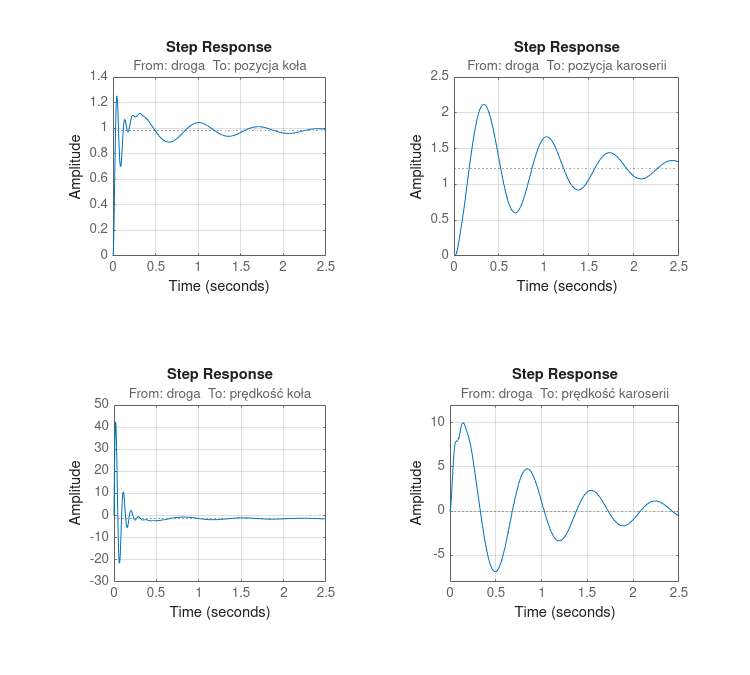

clf
figure
set(gcf, 'Position', [100, 100, 1000, 900]);
subplot(221);
step(G1, 0:0.001:2.5);
grid on;
subplot(222);
step(G2, 0:0.001:2.5);
grid on;
subplot(223)
step(G3, 0:0.001:2.5)
grid on;
subplot(224);
step(G4, 0:0.001:2.5)
grid on;

Bez większego zaskoczenia otrzymaliśmy dokładnie takie same odpowiedzi jak dla wcześniejszej reprezentacj imodelu co potwierdza równoważność obu metod.

# Część prowadzona w Simulinku

Model wykonano również w środowisku Simulink, w tym celu zbudowany model  bloczkowy wygląda następująco:

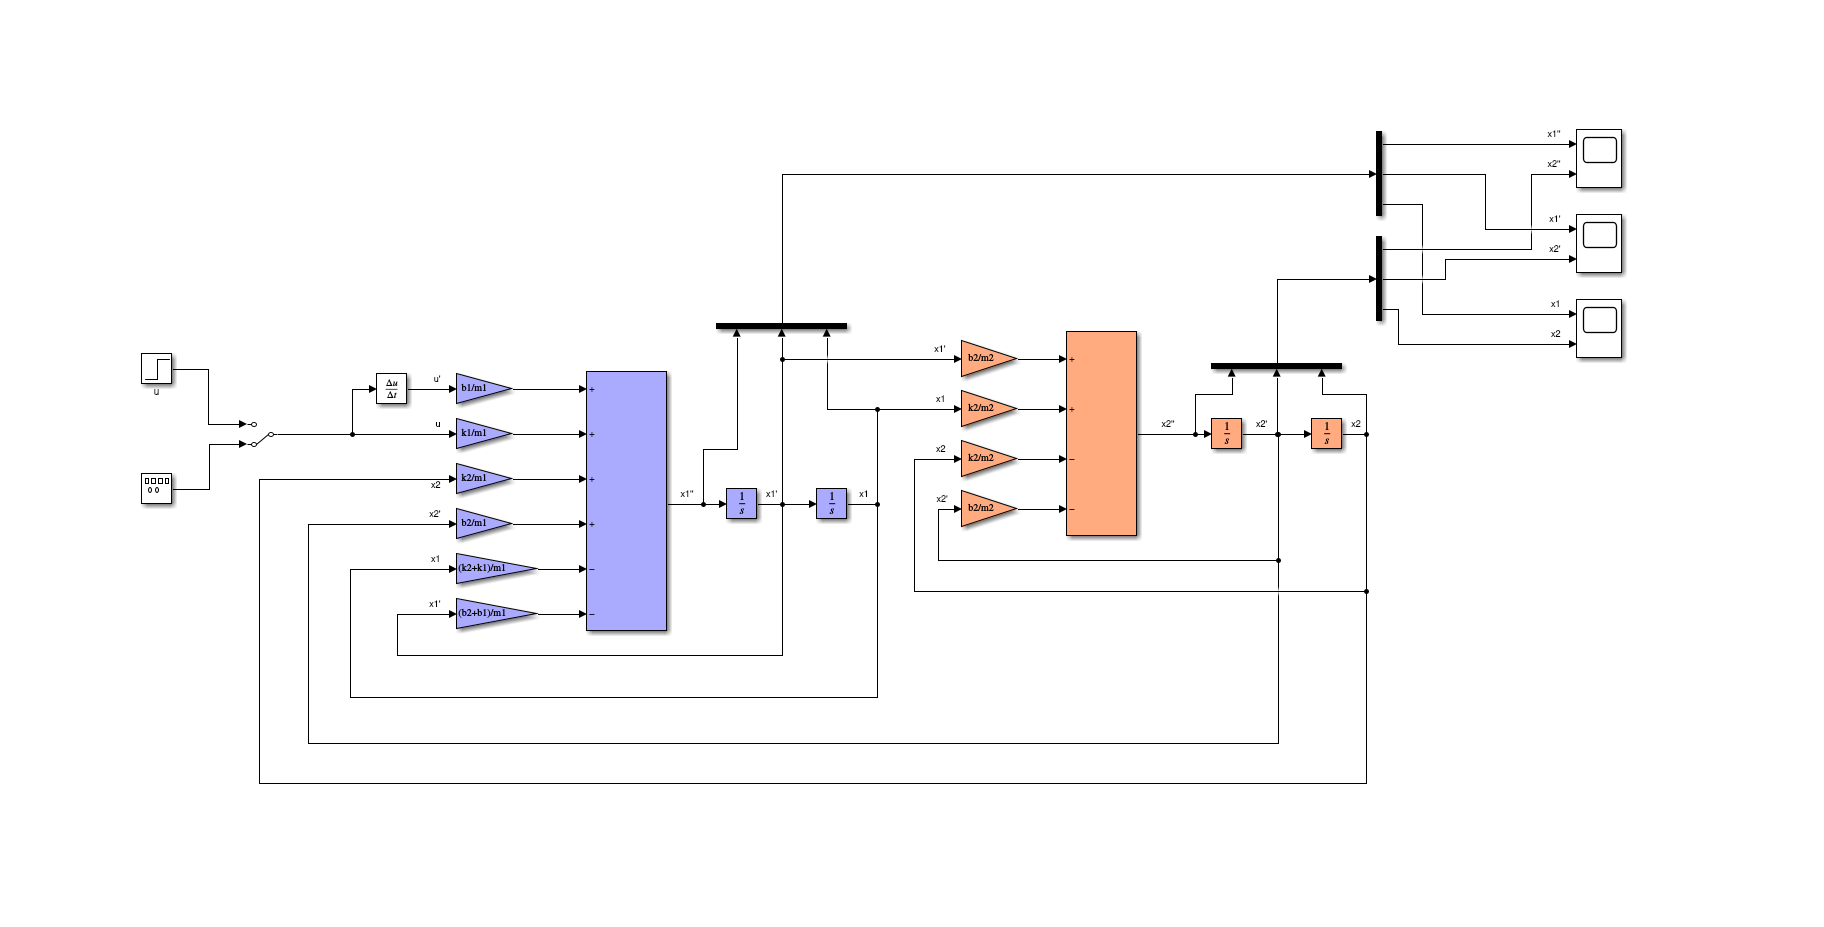

Układ zbudowano korzystając z kilku integratorów, aby odwzorować równanie różniczkowe. Opróćz tego pojawiły się nowe elementy takie jak blok derivative, który potrzebny był w celu uzyskania pochodnej sygnału wejściowego, oraz bloku manual switch, który pozwala przełączać się między sygnałami wejściowymi zachowując struktruę i przejrzystość modelu. Układ poddano wymuszeniu skokowemu oraz serii wymuszeń w postaci synału prostokątnego. Wyniki tych symulacji przedstawiono poniżej:

**Symulacja dla skoku jednostkowego:**

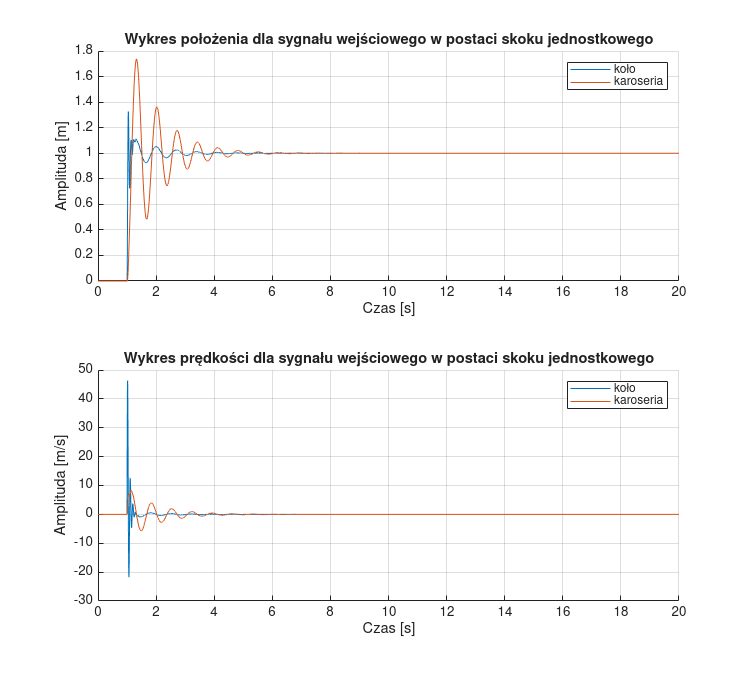

clf
figure
set(gcf, 'Position', [100, 100, 1000, 900]);
subplot(211)
hold on
plot(out.tout, out.jump_signal_x_simulink.signals(1).values)
plot(out.tout, out.jump_signal_x_simulink.signals(2).values)
title("Wykres położenia dla sygnału wejściowego w postaci skoku jednostkowego")
ylabel("Amplituda [m]")
xlabel("Czas [s]")
grid on
legend(["koło", "karoseria"])
hold off

subplot(212)
hold on
plot(out.tout, out.jump_signal_v_simulink.signals(1).values)
plot(out.tout, out.jump_signal_v_simulink.signals(2).values)
title("Wykres prędkości dla sygnału wejściowego w postaci skoku jednostkowego")
ylabel("Amplituda [m/s]")
xlabel("Czas [s]")
grid on
legend(["koło", "karoseria"])
hold off

**Symulacja dla sygnału prostokątnego:**

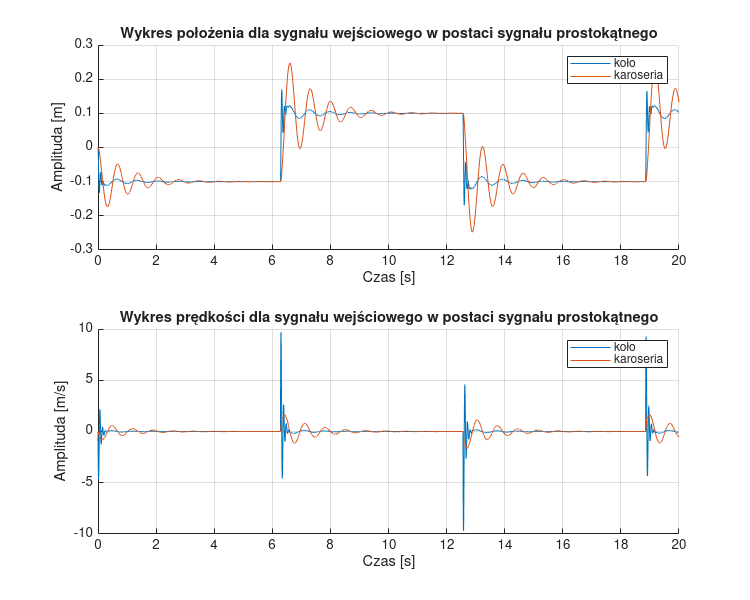

figure
set(gcf, 'Position', [100, 100, 1000, 800]);
subplot(211)
hold on
plot(out.tout, out.square_signal_x_simulink.signals(1).values)
plot(out.tout, out.square_signal_x_simulink.signals(2).values)
title("Wykres położenia dla sygnału wejściowego w postaci sygnału prostokątnego")
ylabel("Amplituda [m]")
xlabel("Czas [s]")
grid on
legend(["koło", "karoseria"])
hold off
subplot(212)
hold on
plot(out.tout, out.square_signal_v_simulink.signals(1).values)
plot(out.tout, out.square_signal_v_simulink.signals(2).values)
title("Wykres prędkości dla sygnału wejściowego w postaci sygnału prostokątnego")
ylabel("Amplituda [m/s]")
xlabel("Czas [s]")
grid on
legend(["koło", "karoseria"])
hold off

Jak można było się spodziewać, również ten sposób zamodelowania istniejącego ukladu dynamiki daje takie same rozwiązania zobrazowane na powyższych wykresach. Ten sposób reprezentacji modelu ma natomiast przewagę nad wcześniejszymi rozwiązaniami, ponieważ w łatwy sposób umożliwia sprawdzenie jak zachowują się wartości przyspieszenia karoserii oraz koła. wartości tych elementów są kluczowe, ponieważ to własnie bezpośrednio z nimi związane są odczucia z jazdy pasażęra.

# Wnioski

Model zawieszenia samochodu dla jednego koła umożliwił analizę dynamicznej reakcji układu na różne wymuszenia, uwzględniając uproszczony model zawierając: masy, tłumieniki i sprężynyi. Symulacje odpowiedzi skokowych wykazały skuteczne tłumienie nierówności – koło reaguje szybciej niż karoseria, co poprawia komfort jazdy, np. podczas wjeżdzania i zjeżdzania  z krawężników. Dodatkowym atutem ćwiczenia było rozwiązanie zagadnieniia przy pomocy kilku metod. Dzięki reprezentacji w przestrzeni stanów w MATLABie uproszczono kod i interpretację wyników. Przejście na model transmitacyjny pozwoliło na porównanie obu metod i potwierdziło ich zgodność. Z kolei symulacje w Simulinku pozwoliły na intuicyjne śledzenie zmian położenia i prędkości oraz uzyskanie informacji o przyspieszeniach, kluczowych dla komfortu jazdy pasażerów. Całość potwierdziła, że przyjęty model skutecznie odwzorowuje właściwości zawieszenia, a środowisko Matlab sprawdza się w symulacji takich układów.